# CIV102 Bridge Design Project 

## MATLAB Source Code 

#### Setting up the variables

close all
clear
L = 1200;                               % Length of bridge
n = 1200;                               % Discretize bridge into 1 mm segments
P = 400;                                % Total weight of train [N]
x = linspace(0, L, n+1);                % x-axis; row vector 0 <= x <= 1200

#### SFD & BMD Generator for variable train locations

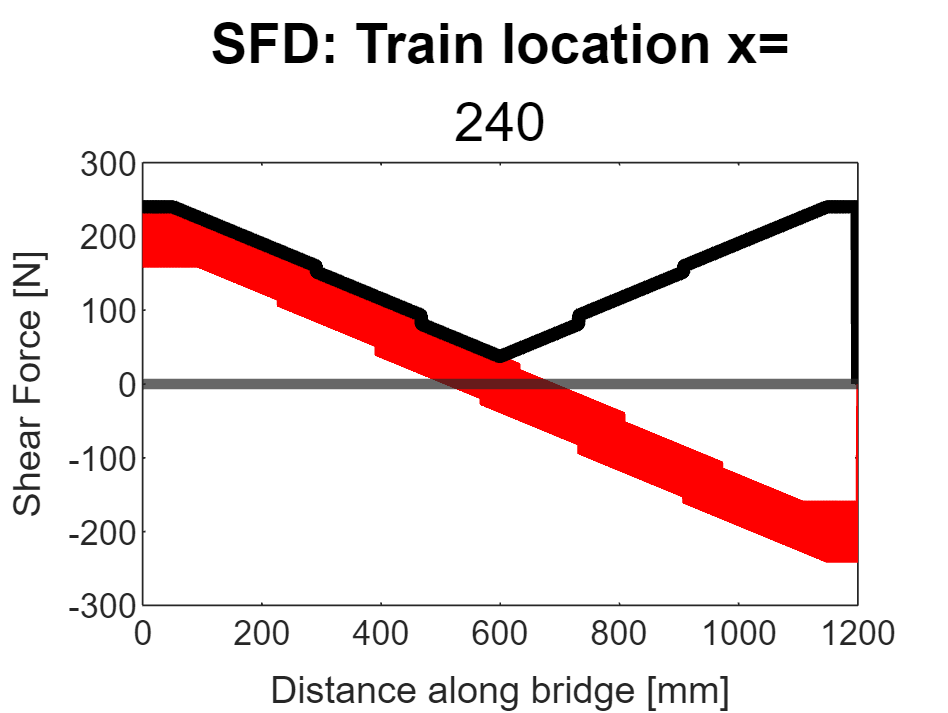

x_train = [52 228 392 568 732 908];     % Train load locations
P_train = [1 1 1 1 1 1] .* P/6;         % Point load at each wheel location
n_train = 240;                          % Number of train locations

SFDi = zeros(n_train+1, n+1);           % 1 SFD for each train location
BMDi = zeros(n_train+1, n+1);           % 1 BMD for each train location
max_BMD = [];

for i = 0:n_train

    x_start = i;                                   % Input start location of train
    x_train_location = x_start + x_train;          % Distance of loads to A
    rB = ((P / 6) * sum(x_train_location)) / L;    % Reaction force at B
    rA = P - rB;                                   % Reaction force at A
    load = zeros(1, 1201);
    applied_load = [rA -P_train rB];  
    
    load(1) = applied_load(1);                          
    load(x_train_location(1)+1) = applied_load(2);
    load(x_train_location(2)+1) = applied_load(3);
    load(x_train_location(3)+1) = applied_load(4);
    load(x_train_location(4)+1) = applied_load(5);
    load(x_train_location(5)+1) = applied_load(6);
    load(x_train_location(6)+1) = applied_load(7);
    load(1201) = applied_load(8);
    SFD = cumsum(load);
    SFDi(i+1, :) = SFD;
    BMD = cumsum(SFD);
    BMDi(i+1, :) = BMD;

    max_BMD(end+1) = max(BMD);

end

% Envelope values; maximum V and M at each mm along bridge
SFDE = max(abs(SFDi));
BMDE = max(BMDi);

% Plots graphs for SFD and Envelope  
figure
plot(x, SFDi, 'r', LineWidth=1)
yline(0, LineWidth=3)
hold on
plot(x, SFDE, 'k', LineWidth=4)
ylabel("Shear Force [N]")
xlabel("Distance along bridge [mm]")
title("SFD: Train location x=", x_start, FontSize=16)

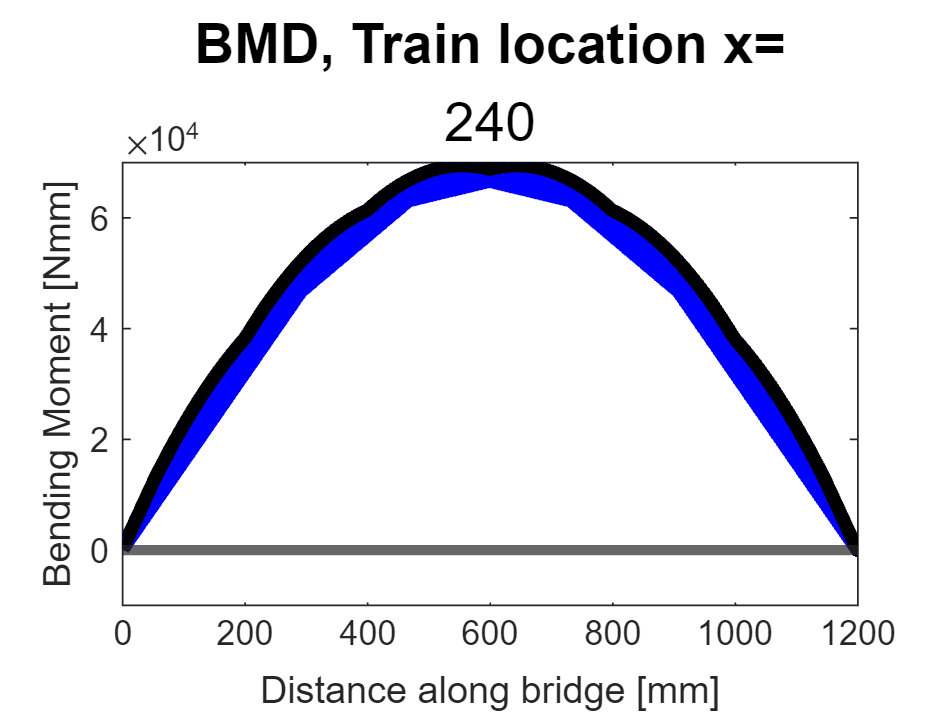

% Plots graphs for BMD and Envelope
figure
plot(x, BMDi,'b', LineWidth=4)
yline(0, LineWidth=3)
hold on
plot(x, BMDE, 'k', LineWidth=4)
ylabel("Bending Moment [Nmm]")
xlabel("Distance along bridge [mm]")
title("BMD, Train location x=", x_start, FontSize=16)

#### Defining Bridge Parameters

%       [xc,  tpw, tph,     sph,    spw, bpw, bph, tabw, tabh]
param = [0,   100, 1.27, (75-1.27), 1.27, 80, 1.27, 5,  1.27;
        1200, 100, 1.27, (75-1.27), 1.27, 80, 1.27, 5,  1.27];

% xc    Location of cross-section change along bridge
% tpw   Top piece width
% tph   Top piece height
% sph   Side piece height
% spw   Side piece width
% bpw   Bottom piece width
% bph   Bottom piece height
% tabw  Tab width 
% tabh  Tab height

% Extracting user input assuming linear relationship
tpw = interp1(param(:,1), param(:,2), x); 
tph = interp1(param(:,1), param(:,3), x); 
sph = interp1(param(:,1), param(:,4), x); 
spw = interp1(param(:,1), param(:,5), x); 
bpw = interp1(param(:,1), param(:,6), x); 
bph = interp1(param(:,1), param(:,7), x); 
tabw = interp1(param(:,1), param(:,8), x); 
tabh = interp1(param(:,1), param(:,9), x); 

total_height = tph + sph + bph; % Total height of bridge

#### Calculate Sectional Properties

% y-bar; location of centroidal axis from bottom of bridge
A   = (tpw.* tph) + 2*(sph.*spw) + 2*(tabw.*tabh) + (bpw.*bph);                
Ay  = (tpw.* tph).*(sph + bph + tph/2) + 2*(sph.*spw).*(sph/2 + bph) ...    
      + 2*(tabw.*tabh).*(tabh/2 + (sph-tabh) + bph) + (bph.*bpw).*(bph/2);    
y_bar = Ay ./ A

y_bar =    49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743   49.2743



% I; second moment of area
I_sum = ((tpw.*(tph.^3) + 2*(spw.*(sph.^3)) + 2*(tabw.*(tabh.^3)) + ...             
        bpw.*(bph.^3))) ./ 12;
I_Ad = (tpw.* tph).*(((sph + bph + tph/2) - y_bar).^2) + 2*((sph.*spw) ...
       .* ((sph/2 + bph)-y_bar).^2) + 2*((tabw.*tabh).*(((tabh/2 + (sph-tabh) ...
       + bph)-y_bar).^2)) + ((bph.*bpw).*((bph/2-y_bar).^2));
I = I_sum + I_Ad

I = 1.0e+05 *

    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892    6.2892


y_bot = y_bar;                  % distance from y-bar to bottom of cross-section
y_top = total_height - y_bar;   % distance from y-bar to top of cross section

% Q center
Q_cent = 2*((y_bar - bph).*1.27.*((y_bar - bph)./2)) + (bph .* bpw).* ...
        (y_bar - (bph./2))

Q_cent = 1.0e+03 *

    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684    7.8684



% Q glue
Q_glue = tph .* tpw .* (y_top - (tph./2))

Q_glue = 1.0e+03 *

    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528    5.2528


#### Calculate Applied Stress

% s = My / I
S_top = BMDE .* y_top ./ I

S_top =     0.0160    0.0321    0.0481    0.0641    0.0801    0.0962    0.1122    0.1282    0.1442    0.1603    0.1763    0.1923    0.2083    0.2244    0.2404    0.2564    0.2724    0.2885    0.3045    0.3205    0.3365    0.3526    0.3686    0.3846    0.4006    0.4167    0.4327    0.4487    0.4648    0.4808    0.4968    0.5128    0.5289    0.5449    0.5609    0.5769    0.5930    0.6090    0.6250    0.6410    0.6571    0.6731    0.6891    0.7051    0.7212    0.7372    0.7532    0.7692    0.7853    0.8013


S_bot = BMDE .* y_bot ./ I

S_bot =     0.0188    0.0376    0.0564    0.0752    0.0940    0.1128    0.1316    0.1504    0.1692    0.1880    0.2068    0.2256    0.2444    0.2632    0.2821    0.3009    0.3197    0.3385    0.3573    0.3761    0.3949    0.4137    0.4325    0.4513    0.4701    0.4889    0.5077    0.5265    0.5453    0.5641    0.5829    0.6017    0.6205    0.6393    0.6581    0.6769    0.6957    0.7145    0.7333    0.7521    0.7709    0.7897    0.8085    0.8274    0.8462    0.8650    0.8838    0.9026    0.9214    0.9402



% t = VQ / Ib
T_cent = (SFDE .* Q_cent) ./ (I .* (spw * 2))

T_cent =     1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821    1.1821


T_glue = (SFDE .* Q_glue) ./ (I .* (tabw * 2))

T_glue =     0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005    0.2005


#### Calculate Material and Thin Plate Buckling Capacities

t = 1.27;   % thickness of members
a = 400;    % distance between diaphgrams
E  = 4000;  
mu = 0.2; 

S_tens  = 30 * ones(1, n+1);
S_comp  = 6 * ones(1, n+1);
T_max   = 4 * ones(1, n+1);
T_gmax  = 2 * ones(1, n+1);
S_buck1 = (((4 * pi^2 * E) / (12 * (1 - mu^2))) .* ...
          (tph ./(bpw - spw)).^2) 

S_buck1 =     3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669    3.5669


S_buck2 = (((0.425 * pi^2 * E) / (12 * (1 - mu^2))) .* (tph ...
          ./ ((tpw - bpw + spw)./2)).^2) 

S_buck2 =    20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696   20.7696


S_buck3 =  (((6 * pi^2 * E) / (12 * (1 - mu^2))) .* (spw ./ (sph + ...
           bph - y_bar - (tabh ./2 ))).^2) 

S_buck3 =    20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338   20.6338


T_buck  = (((5 * pi^2 * E) / (12 * (1 - mu^2))) .* ((spw ./ ...
          (sph-0.635)).^2 + (spw ./ a).^2))

T_buck =     3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338    3.7338


#### **Factor of Safety**

% FOS against each failure mechanism
format shortG
FOS_tens = S_tens ./ S_bot;
FOS_comp = S_comp ./ S_top;
FOS_shear = T_max ./ T_cent;
FOS_glue = T_gmax ./ T_glue;
FOS_buck1 = S_buck1 ./ S_top;
FOS_buck2 = S_buck2 ./ S_top;
FOS_buck3 = S_buck3 ./ S_top;
FOS_buckV = T_buck ./ T_cent;
format short

% Minimum FOS against each failure mechanism
min_FOS_tens = min(FOS_tens)

min_FOS_tens = 5.5138

min_FOS_comp = min(FOS_comp)

min_FOS_comp = 1.2939

min_FOS_shear = min(FOS_shear) 

min_FOS_shear = 3.3837

min_FOS_glue = min(FOS_glue)

min_FOS_glue = 9.9775

min_FOS_buck1 = min(FOS_buck1)

min_FOS_buck1 = 0.7692

min_FOS_buck2 = min(FOS_buck2)

min_FOS_buck2 = 4.4789

min_FOS_buck3 = min(FOS_buck3) 

min_FOS_buck3 = 4.4496

min_FOS_buckV = min(FOS_buckV) 

min_FOS_buckV = 3.1585

#### Min FOS and Failure Load

% Minimum FOS of all FOS
min_FOS = min(abs([FOS_tens FOS_comp FOS_shear FOS_glue FOS_buck1 ...
          FOS_buck2 FOS_buck3  FOS_buckV]))

min_FOS = 0.7692


% Maximum train weight supported by current design
max_weight = min_FOS * P

max_weight = 307.6805

#### Shear Force Capacity and Bending Moment Capacity

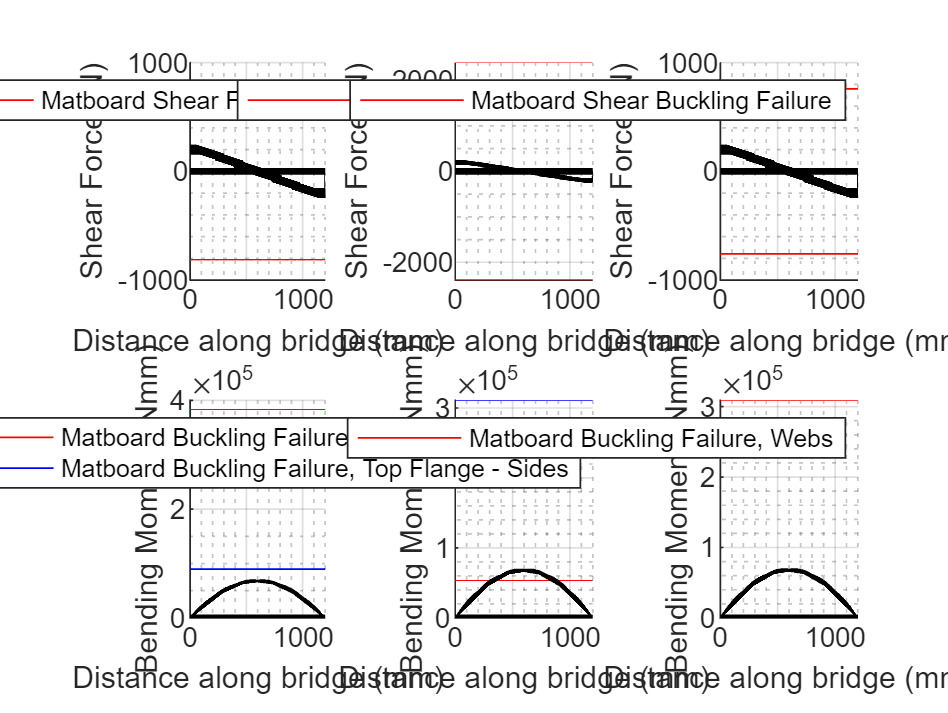

% Calculates shear force and bending moment capacities
Vf_shear =  FOS_shear .* SFDE;
Vf_glue  =  FOS_glue .* SFDE;
Vf_buckV =  FOS_buckV .* SFDE;
Mf_tens  =  FOS_tens .* BMDE;
Mf_comp  =  FOS_comp .* BMDE;
Mf_buck1 =  FOS_buck1 .* BMDE;
Mf_buck2 =  FOS_buck2 .* BMDE;
Mf_buck3 =  FOS_buck3 .* BMDE;

% Plots graphs of SFD and shear force capacities
subplot(2,3,1) 
hold on; grid on; grid minor; 
plot(x, Vf_shear, 'r') 
plot(x, -Vf_shear, 'r') 
plot(x, SFDi, 'k'); 
plot([0, L], [0, 0], 'k', 'LineWidth', 2) 
legend('Matboard Shear Failure') 
xlabel('Distance along bridge (mm)') 
ylabel('Shear Force (N)') 

subplot(2,3,2)
hold on; grid on; grid minor;
plot(x, Vf_glue, 'r')
plot(x, -Vf_glue, 'r')
plot(x, SFDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
legend('Glue Shear Failure')
xlabel('Distance along bridge (mm)')
ylabel('Shear Force (N)')
 
subplot(2,3,3)
hold on; grid on; grid minor;
plot(x, Vf_buckV, 'r')
plot(x, -Vf_buckV, 'r')
plot(x, SFDi, 'k');
plot([0, L], [0,  0], 'k', 'LineWidth', 2)
legend('Matboard Shear Buckling Failure')
xlabel('Distance along bridge (mm)')
ylabel('Shear Force (N)')
 
% Plots graphs of BMD and bending moment capacities
subplot(2,3,4)
hold on; grid on; grid minor;
plot(x, Mf_tens, 'r')
plot(x, Mf_comp, 'b')
plot(x, BMDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
legend('Matboard Tension Failure', 'Matboard Compression Failure')
xlabel('Distance along bridge (mm)')
ylabel('Bending Moment (Nmm)')

subplot(2,3,5)
hold on; grid on; grid minor;
plot(x, Mf_buck1, 'r')
plot(x, Mf_buck2, 'b')
plot(x, BMDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
legend('Matboard Buckling Failure, Top Flange - Mid', ['Matboard ' ...
        'Buckling Failure, Top Flange - Sides'])
xlabel('Distance along bridge (mm)')
ylabel('Bending Moment (Nmm)')

subplot(2,3,6)
hold on; grid on; grid minor;
plot(x, Mf_buck3, 'r')
plot(x, BMDi, 'k');
plot([0, L], [0, 0], 'k', 'LineWidth', 2)
legend('Matboard Buckling Failure, Webs')
xlabel('Distance along bridge (mm)')
ylabel('Bending Moment (Nmm)')